## EXERCISE 1

A toggle switch circuit is defined by the following dynamics equations (parameters provided during the lecture):

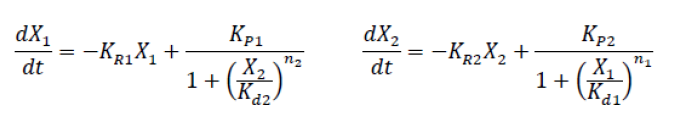

## task 1

Plot the nullclines of the two equations over their vector field.

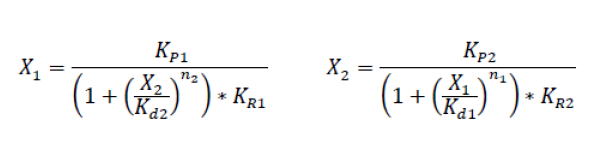

How many fixed points are present? How many are stable?

**Constants and data:**

% K removal
KR_1 = 0.0058;
KR_2 = 0.0058;

% K production
KP_1 = 0.5;
KP_2 = 0.5;

% K dissociation
KD_1 = 40;
KD_2 = 40;

% hill coefficients
n_1 = 3;
n_2 = 3;

**defining the functions needed to to produce the nullcines:**

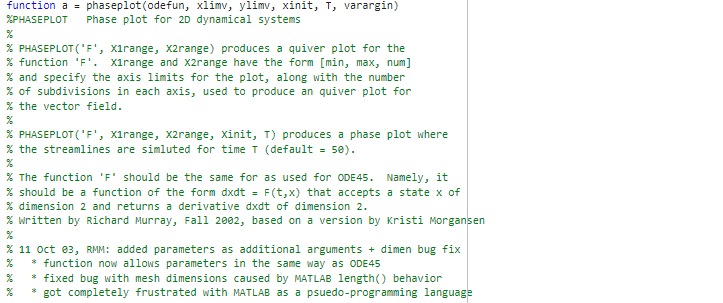

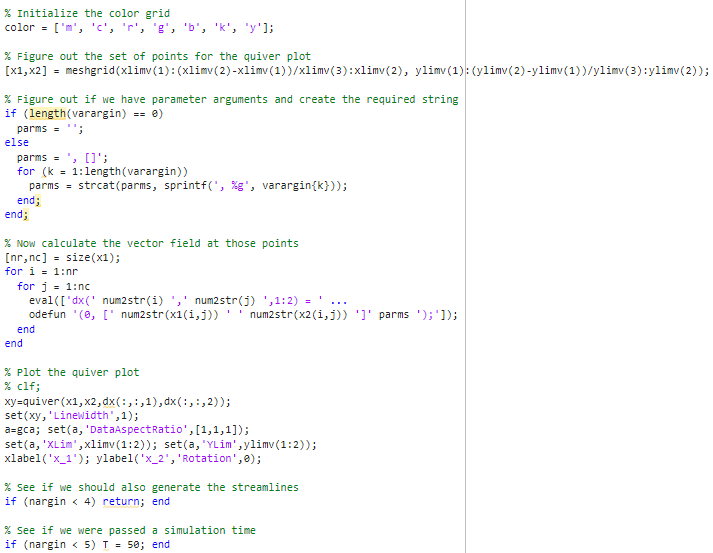

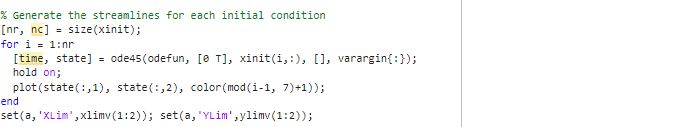

it returns the two concentrations and over the time period.

To solve the system of DE equations the function employs the ode45 sover, and to make it work we specify the equations in the **function toggleswitch**.

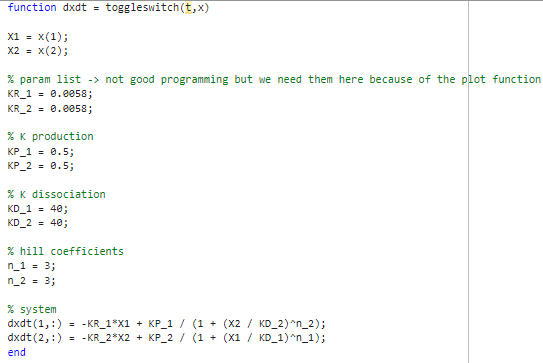

**Proceeding with the task:**

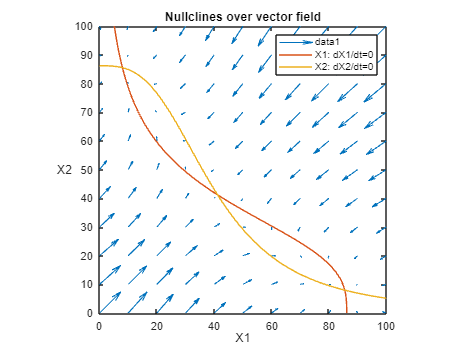

% plot the vector field + nullclines
X_min = 0;
X_max = 100;
grid_size = 10;

figure
phaseplot('toggleswitch',...
    [X_min X_max grid_size],...
    [X_min X_max grid_size]);
title('Nullclines over vector field')
xlabel('X1')
ylabel('X2')

%overlay nullclines
hold on
samples = linspace(X_min,X_max,X_max-X_min+1);
X1 = (1/KR_1)*KP_1./(1+(samples/KD_2).^n_2);
X2 = (1/KR_2)*KP_2./(1+(samples/KD_1).^n_1);
plot(X1,samples, 'DisplayName','X1: dX1/dt=0')
plot(samples,X2, 'DisplayName','X2: dX2/dt=0')                  %notice tat here the terms isolated on left of the given equations are different not the same one as in lab3,ex2,task1 were is the same one, so I need to invert the axis order while plotting
legend()

In the plot we can see that for the low and high fixed point the arrows converge towards the points, so they arestable fixed points. Differently, for the fixed point in the middle, the arrows diverge so it's unstable.

## task 2

Consider the following initial conditions:

1. X10 = 0,        X20 = 10

2. X10 = 40,      X20 = 10

Plot the evolution of the two concentrations over a span of 2 hours for each initial condition. Is an equilibrium reached? Stable or unstable? How long does it take to reach it?

#### case 1:

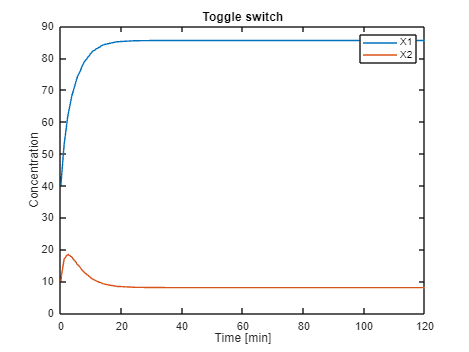

t_0 = 0;
t_max = 3600*2;
X1_0 = 40;
X2_0 = 10;

sol = ode45(@toggleswitch, ...                    % returns a struct object, having the attributes solver, extdata, x, y, stats & idata
            [t_0 t_max], ...                      % [time, X] = ode45(blabla) is basically storing sol.x and sol.y
            [X1_0 X2_0]);            
                                                               

% plot the concentrations in time
figure
plot(sol.x/60,sol.y(1,:),...
     sol.x/60,sol.y(2,:))
title('Toggle switch')
xlabel('Time [min]')
ylabel('Concentration')
legend('X1','X2')

We can notice that we have 31 time instances, this is done automatically by the solver. It decides to partition the time interval in order to have a smooth plot.

From the plot we can see that in 20 min we reach the plateau, values remain constant and so we reached a stable equilibrium concentration.

#### case 2:

Even with different concentration we reach a stable concentration. (notice also that they also "swap position")

## task 3

Draw the phase plot of the dynamical system and the streamline for each initial condition.

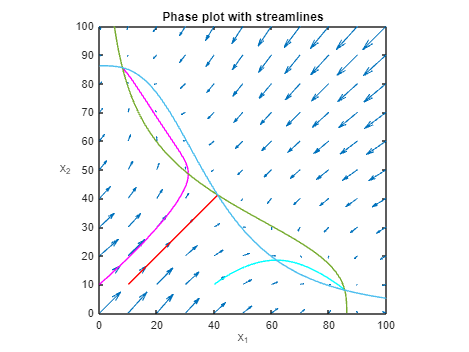

% phase plot with streamlines
X1_0_1 = 0;
X2_0_1 = 10;
X1_0_2 = 40;
X2_0_2 = 10;
X1_0_var = 10;
X2_0_var = 10;
t_max = 3600*2*10^(0);            % 7,2s    1,2min     12min     2h
figure
xlabel('X1')
ylabel('X2')
phaseplot('toggleswitch',...
    [X_min X_max grid_size],...
    [X_min X_max grid_size],...
    [X1_0_1 X2_0_1; X1_0_2 X2_0_2; X1_0_var X2_0_var;],...
    t_max);         %tells the function for how long to plot the streamlines
title('Phase plot with streamlines')

hold on
samples = linspace(X_min,X_max,X_max-X_min+1);
X1 = (1/KR_1)*KP_1./(1+(samples/KD_2).^n_2);
X2 = (1/KR_2)*KP_2./(1+(samples/KD_1).^n_1);
plot(X1,samples, 'DisplayName','X1: dX1/dt=0')
plot(samples,X2, 'DisplayName','X2: dX2/dt=0')                                           

**Streamlines** show out the **evolution of the concentration** of our elements. In the first case the system goes to the fixed point X_high, in the second case it goes to the fixed point X_low.

## task 4

Now consider this initial condition:

X10 = 60             X20 = 60

Plot the evolution of the two concentrations over a span of 6 hours. What happens in this case? Draw the corresponding streamline over the phase plot.

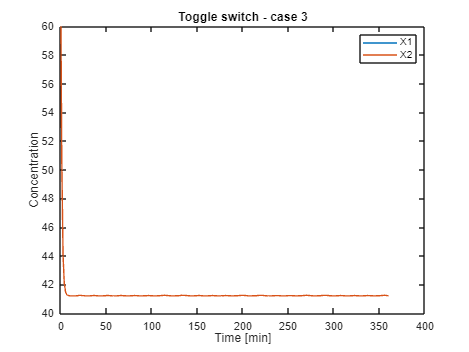

t_max = 3600*6;  % t_max = 21600
X1_0 = 60;
X2_0 = 60;
sol3 = ode45(@toggleswitch, ...
            [0 t_max], ...
            [X1_0 X2_0]);

% plot the concentrations over the time
figure
plot(sol3.x/60,sol3.y(1,:),...
     sol3.x/60,sol3.y(2,:))
title('Toggle switch - case 3')
xlabel('Time [min]')
ylabel('Concentration')
legend('X1','X2')

Appearently we have only X_2, but this is only because X_1=X_2. Both start from 60 and slow down very quicly.

Then they reach the value 41 -> we reached an equilibrium point but it's unstable.

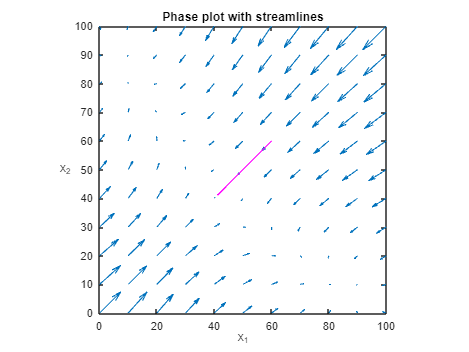

figure
xlabel('X1')
ylabel('X2')
phaseplot('toggleswitch',...
    [X_min X_max grid_size],...
    [X_min X_max grid_size],...
    [X1_0 X2_0],...
    t_max); %tells the function for how long to plot the streamlines
title('Phase plot with streamlines')

We start on the diagonal (X_1 = X_2) the start initial conditions in which the two concentrations are equals are the only ones that allow you to reach this unstable equilibrium. Anything else will lead eventually to the switch behaviour, this is a very special case.

## EXERCISE 2

A repressilator circuit is defined by the following dynamics equations for each of its three repressors (parameters provided during the lecture):

**theory recap:**

Repressilator: composed by three genes that represses each other. 

In this case we will have a realistic representation of the circuit because we have both the equations for the transcript product ( ) and the protein product ( ) .

parameters.:

- : production term

-       : removal term                                  (how quickly the translation happens or more in general, how quickly the transcription product is consumed)

-             : maximum transcription rate          (If you have no repression, then we reach this transcription rate. As   increase our transcription slows down.)

-            : leakage transcription rate              (models the fact that even if we have a lot of repressors bound to our TSS some transcription may still happen, usually is a small number)

-           : how fast the protein gets consumed    

-             : Translation coefficient

## task 1

Consider the following initial conditions:

m10 = 0             m20 = 0             m30 = 0

p10 = 200           p20 = 0                 p30 = 0

Plot the evolution of the concentration of the three proteins over a span of 6 hours. Which kind of behavior do you observe? How long does it take to reach stability?

% mRNA and protein degradation rates [1/s]
mRNA_half_life = 120;
Km = log(2) / mRNA_half_life;
protein_half_life = 600;
Kp = log(2) / protein_half_life;

% translation coefficient [proteins / transcripts* s]
translation_efficiency = 20;
average_mRNA_lifespan = 1 / Km;
T = translation_efficiency / average_mRNA_lifespan;

% max transcription rate [transcripts / s]
gamma_1 = 0.5;
gamma_2 = 0.5;
gamma_3 = 0.5;

% dissociation constant (of repressor from its target promoter)
Kd_1 = 40;
Kd_2 = 40;
Kd_3 = 40;

% Hill coefficients
n_1 = 2;
n_2 = 2;
n_3 = 2;

% leakage transcription rate [transcripts / s] (i.e, transcription rate if
% promoter region bound by repressor)
gamma_0 = 5e-4;

defining the repressilator function

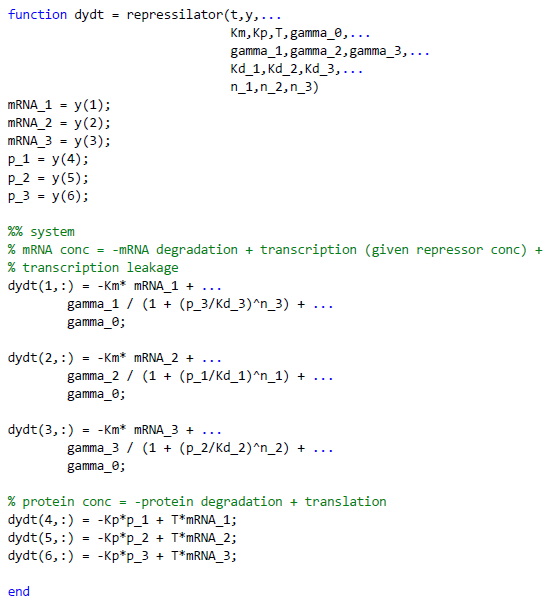

We will have a system with 6 differential equations, so we will not be able to produce the nullclines but we can do the plot of the concentration over the time.

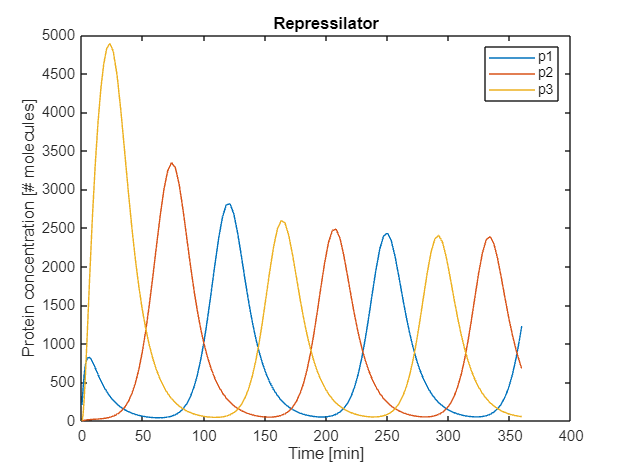

t_0 = 0;
t_max = 3600*6;
m1_0 =30;
m2_0 = 0;
m3_0 = 0;
p1_0 = 200;
p2_0 =0;
p3_0 = 0;
Kp = Kp * 1;

% ode45 again, with 6 initial conditions + all parameters
sol = ode45(@repressilator, ...                             % function used to define the system
            [t_0 t_max],...                                 % time interval
            [m1_0 m2_0 m3_0 p1_0 p2_0 p3_0],...             % initial parameter of DE
            [],...                                          % empty 'options' array for ode45
            Km,Kp,T,gamma_0,gamma_1,gamma_2,gamma_3,Kd_1,Kd_2,Kd_3,n_1,n_2,n_3);

% plot concentrations
figure
plot(sol.x/60,sol.y(4,:), ...
     sol.x/60,sol.y(5,:), ...
     sol.x/60,sol.y(6,:))
title('Repressilator')
xlabel('Time [min]')
ylabel('Protein concentration [# molecules]')
legend('p1','p2','p3')

We can see immediatly the oscillations: the equilibrium is the **time between two peaks of the same proteins (more or less 2h**). 

**Why **do we have a **strange start**? 

P2 and P3 start from 0 concentration while P1 starts from 200:             

so P1 represses P2 --> until P1 is not consumed P2 can't be produced, the absence of P2 makes P3 spike up. Then as P3 grows, since it represses P1 it start collapsing (after a small increase). 

The **initial amount of proteins will influence how other proteins spike up**. 

**Anyway, in some time all the proteins reach the same hight**, that's the equilibrium point.

## task 2

Now consider, separately, the following variations:

m10 = 30

p20 = 100

How does the behavior of the system change?

#### **UPDATING ONLY M10 FIRST:**

Now we have 30 molecules of mRNA1 so the **spiking effect seen before is amplified **because the production p2 is more delayed because we don't only have transcripts of p1  but also the protein, so until p1 is there p2 is not produced so p3 is free to spike up 50% more than before. 

The equilibrium cycle still be around 2h. So the initial concentrations don't influence the behaviour of the system at the equilibrium, they only influence the initial  behaviour.

#### **UPDATING BOTH INITIAL CONCENTRATIONS:**

Now the situation is different: we **don**'**t have spikes before the equilibrium concentration value**. The first small spike is p1. The difference with case1 is that we have some p2 at the beginning so p3 is not free to spike up. The delay in p3 production allows p1 to spike a bit more. 

Again, we have a cycle duration about 2h.

## task 3

 What happens if we double the protein degradation rate 𝐾𝑝?

Changing the removal rate **produce a shrinkage in the equilibrium time**. We are going to have **shorter cycles **because **proteins get used quicker**. Now the cycle duration is about 73 min compared to 126, we lost 40% of the time. Kp is not the only term influencing how quick things happend so it's hard predicting how much it will shrink oscillaiton time.

We don't have the high spike of p3 because p1 gets used quicker so p2 can be produced before and p3 has not the time to spike up. Anyway, we can always say that p3 is the first to spike, even if the spike is not higher than the equilibrium one.